# Compress Dynamic Range of HDR Image Using Edge-Preserving Multiscale Decompositions

Load a high dynamic range (HDR) image into the workspace.


with_clippingNogamma_HDR = hdrread('with_clipping_withoutgamma.hdr');
with_clipping_HDR = HDR;




Convert the HDR image to a low dynamic range (LDR) image using the basic tone mapping function [`tonemap`](docid:images_ref.bvh66m9). Display the result. The LDR image has an acceptable dynamic range but colors are muted.

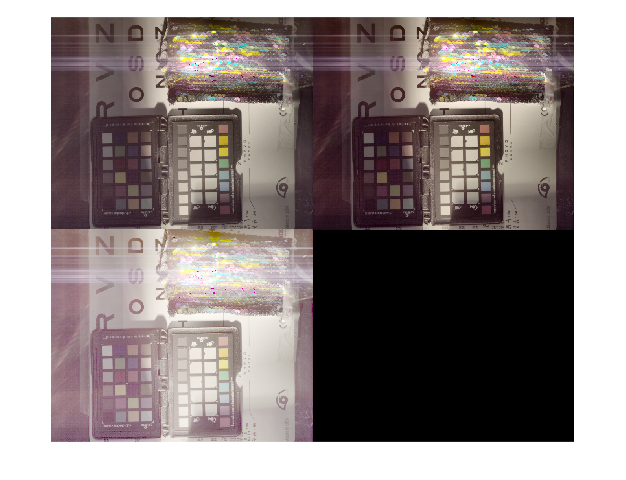

LDR1 = tonemap(with_clipping_HDR);
LDR2 = tonemap(with_clippingNogamma_HDR);
LDR3 = imadjust(LDR2,[],[],0.35);
montage({LDR1,LDR2, LDR3})

%imshow(LDR1)

Repeat the conversion using the `tonemapfarbman` function with default argument values. Display the result. Colors appear more saturated than in the LDR image created using the `tonemap` function. However, the image is bright and has poor contrast, such as in the shadow of the tree. The brightness and poor contrast indicate that the default value of `'Exposure'` is too large.

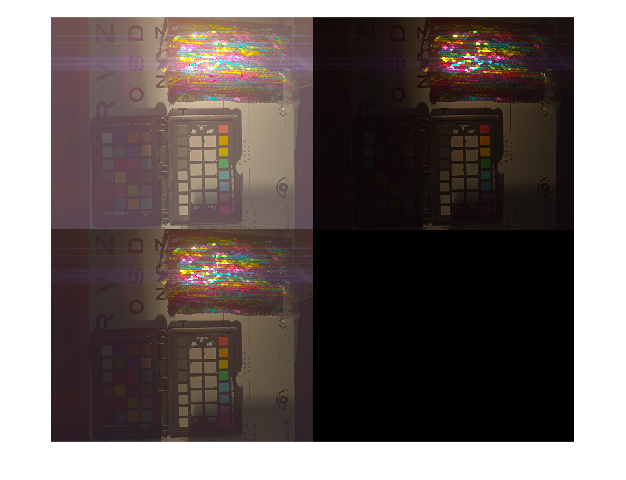

RGB1 = tonemapfarbman(with_clipping_HDR);
RGBtwo = tonemapfarbman(with_clippingNogamma_HDR);
RGB3 = imadjust(RGBtwo,[],[], 0.6);
montage({RGB1,RGBtwo, RGB3})

Repeat the conversion using the `tonemapfarbman` function with a lower value of `'Exposure'` to darken the image. Display the result. The image contrast is improved. The image also shows a decrease in the clipping of pixel values in bright regions, such as the sky, road, and monitor.

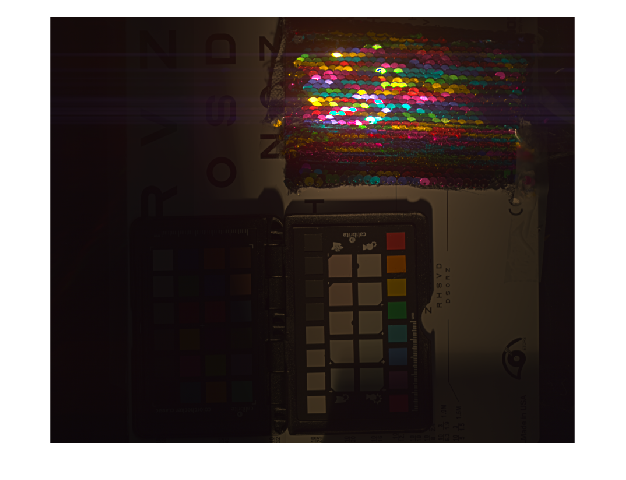

RGB2 = tonemapfarbman(with_clippingNogamma_HDR,'Exposure',3);
RGB4 = imadjust(RGB2,[],[], 0.42);
imshow(RGB2)

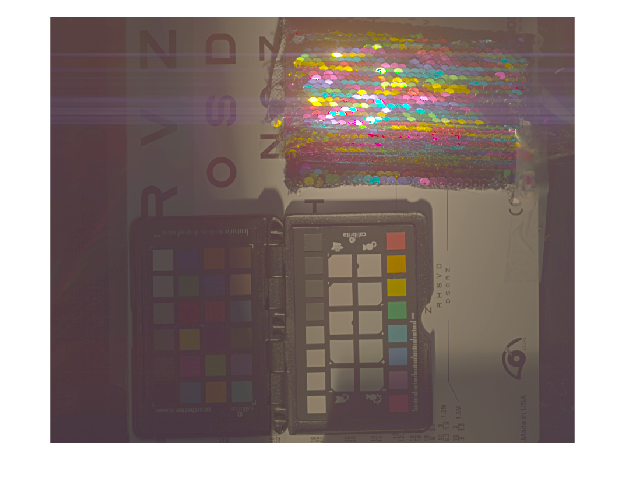

imshow(RGB4)

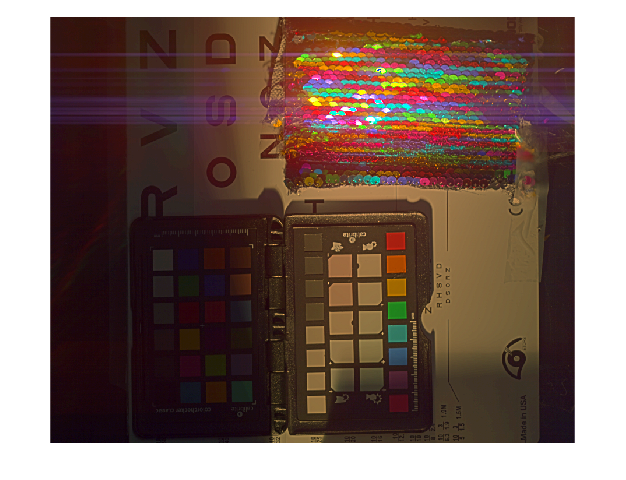

%Applying imreducedhaze
A = imcomplement(RGB2);
B = imreducehaze(A);
B = imcomplement(B);
imshow(B)

*Copyright 2018 The MathWorks, Inc.*